# Muon Angular Distribution

d = 0.52; %m
err_d = 1/sqrt(12)*10^(-3); %m
h = [0; 0.447; 0.224; 0.068; 0.52]; %m
err_h = 0.04/sqrt(12); %m


$${\mathrm{cos}}^2 \theta ={\left(\frac{\sqrt{d^2 -h^2 }}{d}\right)}^2 ={\left(\sqrt{1-{\left(\frac{h}{d}\right)}^2 }\right)}^2 =1-{\left(\frac{h}{d}\right)}^2$$



$$\sigma_{\cos^2 \theta } =2\left(\frac{h}{d}\right)\sigma \left(\frac{h}{d}\right)=2\left(\frac{h}{d}\right)\sqrt{{\left(\frac{h}{d }\right)}^2 \sigma_d^2 +\sigma_h^2 }=2\left(\frac{h}{d^2 }\right)\sqrt{{\left(\frac{h}{d }\right)}^2 \sigma_d^2 +\sigma_h^2 }$$


cos_quadro = 1-(h/d).^2;
err_cos_quadro = 2*h./(d.^2).*sqrt((h.*err_d./d).^2 + err_h.^2);

n_eventi = [4351; 1840; 3124; 3059; 855];
err_n_eventi = sqrt(n_eventi);
durata = [19*60+47.88; 35*60+40.79; 20*60+23.58; 14*60+40.07; 49*60+25.59]; %s
err_durata = 0.2/sqrt(12); % what we were able to distinguish from the chronometer
rate = n_eventi./durata;


$$\sigma_{\mathrm{durata}} =\sqrt{{\left(\frac{\partial \mathrm{rate}}{\partial \mathrm{durata}}\right)}^2 \sigma_{\mathrm{durata}}^2 +{\left(\frac{\partial \mathrm{rate}}{\partial \mathrm{eventi}}\right)}^2 \sigma_{\mathrm{eventi}}^2 }=\sqrt{{\left(\frac{\mathrm{eventi}}{{\mathrm{durata}}^2 }\right)}^2 \sigma_{\mathrm{durata}}^2 +{\left(\frac{1}{\mathrm{durata}}\right)}^2 \sigma_{\mathrm{eventi}}^2 }=\frac{1}{\mathrm{durata}}\sqrt{{\left(\frac{\mathrm{eventi}}{{\mathrm{durata}} }\right)}^2 \sigma_{\mathrm{durata}}^2 +\sigma_{\mathrm{eventi}}^2 }$$


close 
err_rate = 1./durata.*sqrt((n_eventi.*err_durata./durata).^2 + err_n_eventi.^2)

err_rate =     0.0555
    0.0200
    0.0457
    0.0628
    0.0099


fit_eq = 'm*x+q';
f=fit(cos_quadro,rate,fit_eq,'StartPoint',[4 0])

f =      General model:
     f(x) = m*x+q
     Coefficients (with 95% confidence bounds):
       m =       3.329  (2.485, 4.173)
       q =      0.1315  (-0.4886, 0.7515)

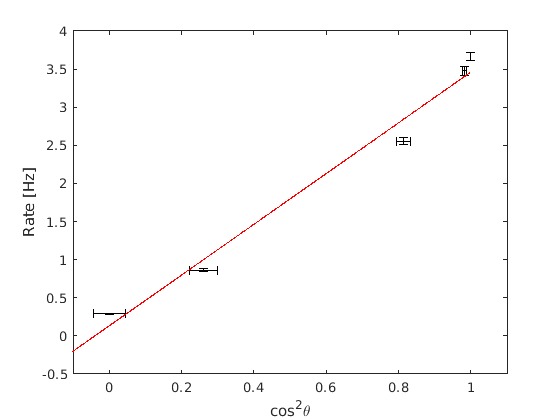


figure()
errorbar(cos_quadro,rate,err_rate,'linestyle', 'none','color', 'k')
hold on;
errorbar(cos_quadro,rate,err_cos_quadro, 'horizontal',  'linestyle', 'none','color', 'k')
hold on;
plot(f)
xlabel('cos^2\theta')
ylabel('Rate [Hz]')
xlim([-0.1 1.1])
legend('off')

alpha=atan(27.5/(2*31))

alpha = 0.4175

omega=2*pi*(1-cos(alpha))

omega = 0.5396